%% Import and select data & Graph Cumulative Returns to Assets
clear;clc;
cd 'Exercise Set 5'\; 
%Read Portfolio Asset Classes
tblAssets = readtable('ExcerciseSet1_YuanzhanGao_AdityaKumar.xlsx','sheet','Returns_All');

date = datetime(tblAssets.Date);
% remove NaN rows
date(1, :) = [];
date(361:365, :) = [];
M = [tblAssets(2:361, 2:21)];
R = corrcoef(M{:,:}, 'Rows', 'complete');

corr_table = array2table(R, 'VariableNames',M.Properties.VariableNames, 'RowNames',M.Properties.VariableNames);
disp(corr_table);

                     SPXIndex    USGG10YRIndex    MXCNIndex    MXWOUIndex    SPGSCITRIndex     RTYIndex     LF98TRUUIndex    LBUSTRUUIndex    BCIT5TINDEX    MXWDINDEX    EPRAIndex    LEGATRUHIndex    DWRTFTIndex    LT09TRUUIndex    PUTIndex     MXEFIndex    RUGLIndex     LUMSTRUUIndex    LD19TRUUIndex    CMBSIndex
                     ________    _____________    _________    __________    _____________    __________    _____________    _____________    ___________    _________    

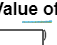


% reverse order to get correct date column
date_ordered = flip(date, 1);
M = [tblAssets.SPXIndex, tblAssets.USGG10YRIndex, tblAssets.MXCNIndex, tblAssets.MXWOUIndex, tblAssets.SPGSCITRIndex, tblAssets.RTYIndex];
AssetNames = {'SPX', 'USGG10YR', 'MXCNI', 'MXWOUI', 'SPGSCITRI', 'RTY'}; 
% % Drop unwanted rows and calculate cumulative returns
M(362:366, :) = [];
% set first row equal 0, so 1+0 = 1
M(1, :) = 0;
cum_M = cumprod(1+M);
% remove the first row for unmatched dimensionality
cum_M(1, :) = [];
% plot cumulative return of 1 dollar
figure(1);
plot(date_ordered, cum_M); title('Cumulative Value of $1 Investment');legend('SPX', 'USGG10YR', 'MXCNI', 'MXWOUI', 'SPGSCITRI', 'RTY');grid on;

% Table for cumulative return and annualized monthly (mean) return
total_month = size(cum_M, 1);
return_table = table([cum_M(360, 1);cum_M(360, 2);cum_M(360, 3);cum_M(360, 4);cum_M(360, 5);cum_M(360, 6);], ...
    [cum_M(360, 1)^(12/total_month)-1;cum_M(360, 2)^(12/total_month)-1;cum_M(360, 3)^(12/total_month)-1;cum_M(360, 4)^(12/total_month)-1;cum_M(360, 5)^(12/total_month)-1;cum_M(360, 6)^(12/total_month)-1;], ...
    'RowNames', AssetNames, ...
    'VariableNames',{'Cumulative Dollar Return($)','Annualized Mean Return(%)'});

disp(return_table);

                 Cumulative Dollar Return($)    Annualized Mean Return(%)
                 ___________________________    _________________________

    SPX                     15.808                      0.096384         
    USGG10YR               0.57954                      -0.01802         
    MXCNI                   1.2983                       0.00874         
    MXWOUI                  2.7429                      0.034206         
    SPGSCITRI               1.4607                       0.01271         
    RTY                     11.554                      0.084987         



## 2.a.	Set Portfolio Optimization Constraints & Options

% Construct the variance/Covariance matrix

%r remove first row of M (currently 0 which is added for 1$ cum return
%calculation)
if size(M, 1) == 361
    M(1, :) = [];
end

T = size(M, 1);
for t = 36:T
    V = cov(M(t-35:t,:)); 
    Vcov(:,:,t) = V; Vcond(t) = cond(V); 
end

% calculate monthly mean return (not annualized, because I don't want to:)
mean_return = (prod(1+M).^(1/T)-1);

% Set up conditions for quadratic programming
nAssets = size(M, 2); r = 0.0055;     % number of assets and desired return (use monthly return here)
Aeq = ones(1,nAssets); beq = 1;              % equality Aeq*x = beq (all sum to 1)
Aineq = -mean_return; bineq = -r;            % inequality Aineq*x <= bineq
% why negative:
% since quadprog's 3rd and 4th parameter only sets up the constraint as
% A*x < b, to reach a return greater than designated r, the return needs
% to be greater than r in absolute value, or less than -r when the return
% and r are both positive.


lb = zeros(nAssets,1); ub = ones(nAssets,1); % bounds lb <= x <= ub (no shorting)
c = zeros(nAssets,1);                        % objective has no linear term; set it to zero
% Select Options for Quadprog
options = optimset('Algorithm','interior-point-convex');
options = optimset(options,'Display','off','TolFun',1e-10);

## Optimize three base and three stress cases

dateStr = datestr(date);
n = strmatch('30-Jul-2010',dateStr,'exact');
% Base case:  
Vbase = cov(M);  % Average through whole sample
wmvBase = quadprog(Vbase,c,[],[],Aeq,beq,[],[],[],options); % allow shorting
wBase = quadprog(Vbase,c,Aineq,bineq,Aeq,beq,lb,ub,[],options); % greater or equal than target return; does not allow shorting
wrpBase = riskBudgetingPortfolio(Vbase);

% Stress case
Vstress = Vcov(:,:,n);  % n = location for '30-Jul-2010'
wmvStress = quadprog(Vstress,c,[],[],Aeq,beq,[],[],[],options); 
wStress = quadprog(Vstress,c,Aineq,bineq,Aeq,beq,lb,ub,[],options);
wrpStress = riskBudgetingPortfolio(Vstress);

## 2. Continue: Table Result

% 2.a. Portofolio Weights 
PortWts = table(wmvBase, wmvStress,wBase,wStress,wrpBase,wrpStress,'RowNames',AssetNames);
disp(PortWts);

                  wmvBase      wmvStress      wBase        wStress      wrpBase    wrpStress
                 __________    _________    __________    __________    _______    _________

    SPX             0.85211       2.823         0.6476             1     0.2063     0.21756 
    USGG10YR        0.10824    0.017399       0.096755    6.7709e-09    0.15013     0.11002 
    MXCNI        -0.0085448     0.23372       4.09e-08    1.5397e-09      0.123     0.16363 
    MXWOUI          0.11895    -0.78797       0.062968     1.544e-09     0.1862      0.1696 
    SPGSCITRI       0.19825    0.030746        0.19268    3.1109e-09    0.17819     0.18006 
    RTY              -0.269     -1.3169   

% 2.b. portofolio risks
riskmvBase = round(sqrt(wmvBase'*(12*Vbase)*wmvBase), 3);
riskmvStress = round(sqrt(wmvStress'*(12*Vstress)*wmvStress), 3);

riskBase = round(sqrt(wBase'*(12*Vbase)*wBase),3);
riskStress = round(sqrt(wStress'*(12*Vstress)*wStress),3);

riskParityBase = round(sqrt(wrpBase'*(12*Vbase)*wrpBase),3);
riskParityStress = round(sqrt(wrpStress'*(12*Vstress)*wrpStress),3);

riskScenarios = table(riskmvBase, riskmvStress, riskBase,riskStress,riskParityBase,riskParityStress, ...
    'VariableNames',{'minVarianceBase', 'minVarianceStress', 'MaxSharpeBase','MaxSharpeStress','RiskParityBase','RiskParityStress'});
disp(riskScenarios);

    minVarianceBase    minVarianceStress    MaxSharpeBase    MaxSharpeStress    RiskParityBase    RiskParityStress
    _______________    _________________    _____________    _______________    ______________    ________________

         0.133               0.092              0.136             0.136             0.149              0.168      



% 2.c. MCR
MCR = table(round(12*Vbase*wmvBase/riskmvBase,3), round(12*Vstress*wmvStress/riskmvStress,3), round(12*Vbase*wBase/riskBase,3), round(12*Vstress*wStress/riskStress,3), round(12*Vbase*wrpBase/riskParityBase,3), round(12*Vstress*wrpStress/riskParityStress,3),'VariableNames', {'MCRminVarBase', 'MCRminVarStress', 'MCRBase', 'MCRStress', 'MCRRPBase', 'MCRRPStress'},'RowNames', AssetNames);
disp(MCR);

                 MCRminVarBase    MCRminVarStress    MCRBase    MCRStress    MCRRPBase    MCRRPStress
                 _____________    _______________    _______    _________    _________    ___________

    SPX              0.133             0.093          0.136       0.135         0.12         0.129   
    USGG10YR         0.133             0.093          0.136       0.209        0.165         0.255   
    MXCNI            0.133             0.093          0.145       0.151        0.201         0.171   
    MXWOUI           0.133             0.093          0.136       0.164        0.133         0.165   
    SPGSCITRI        0.133             0.093          0.136       0.145        0.139         0.156

% 2.d. Attribution
riskBudget_mv_Base = round((12*Vbase*wmvBase/riskmvBase).*wmvBase,3);
riskBudget_mv_Stress = round((12*Vstress*wmvStress/riskmvStress).*wmvStress,3);
riskBudget_Base = round((12*Vbase*wBase/riskBase).*wBase,3);
riskBudget_Stress = round((12*Vstress*wStress/riskStress).*wStress,3);
riskBudget_rp_Base = round((12*Vbase*wrpBase/riskParityBase).*wrpBase,3);
riskBudget_rp_Stress = round((12*Vstress*wrpStress/riskParityStress).*wrpStress,3);
RiskBudget = table(riskBudget_mv_Base, riskBudget_mv_Stress, riskBudget_Base, riskBudget_Stress, riskBudget_rp_Base, riskBudget_rp_Stress, 'VariableNames', {'RiskBudgetminVarBase', 'RiskBudgetminVarStress', 'RiskBudgetBase', 'RiskBudgetStress', 'RiskBudgetRPBase', 'RiskBudgetRPStress'}, 'RowNames',AssetNames);
disp(RiskBudget);

                 RiskBudgetminVarBase    RiskBudgetminVarStress    RiskBudgetBase    RiskBudgetStress    RiskBudgetRPBase    RiskBudgetRPStress
                 ____________________    ______________________    ______________    ________________    ________________    __________________

    SPX                  0.113                    0.262                0.088              0.135               0.025                0.028       
    USGG10YR             0.014                    0.002                0.013                  0               0.025                0.028       
    MXCNI               -0.001                    0.022                    0                  0               0.025                0.028       
    MXWOUI   

## 3. Estimate VaR at the 1-percent level for each of the six portfolios.  Tell me exactly what these mean for the three portfolios under both the  Base and Stress cases.

% Expected Return for each of the portofolio

% Expected Return - minimal variance (Base)
Rmv_base =  mean_return * wmvBase;
Rmv_stress = mean_return* wmvStress;
R_base = mean_return * wBase;
R_stress = mean_return* wStress;
Rrp_base = mean_return * wrpBase;
Rrp_stress = mean_return * wrpStress;

VaR_01 = ((1+[Rmv_base, Rmv_stress, R_base, R_stress, Rrp_base, Rrp_stress]).^12 -1) + norminv([0.005, 0.995])'*[table2array(riskScenarios)];
Var01_table = array2table(VaR_01, 'RowNames',{'Upper Bound', 'Lower Bound'}, 'VariableNames', {'R_mv_Base', 'R_mv_Stress', 'R_Base', 'R_Stress', 'R_rp_Base', 'R_rp_Stress'});
disp("We are 99% confident that the annualized expected return for each portofolio is as follows:");

We are 99% confident that the annualized expected return for each portofolio is as follows:


disp(Var01_table);

                   R_mv_Base    R_mv_Stress     R_Base     R_Stress    R_rp_Base    R_rp_Stress
                   _________    ___________    ________    ________    _________    ___________

    Upper Bound    -0.27968      -0.10058      -0.28587    -0.25393     -0.3444      -0.39144  
    Lower Bound     0.40549       0.37338       0.41476      0.4467      0.4232       0.47403  



## Question 4

% 4.a
%Base case target Return
R_Base_total = M*wBase;
% Read in BlackRock factor
Factors = readtable('ExcerciseSet1_YuanzhanGao_AdityaKumar.xlsx','sheet','BLK_AQR');
dateFactor = datetime(Factors.DATE);
BR_factors = [Factors.RealRates, Factors.Inflation, Factors.Credit, Factors.Economic, Factors.EmergingMarkets, Factors.Liquidity];
[T,k]= size(BR_factors); 

% Trim the BR_factors matrix to date we are interested in
% StartDate is Jan-93
start_date = strmatch('31-Jan-1993', datestr(dateFactor), 'exact');
% EndDate is Dec-22, which the BR_factors do not have in the dataset; we
% will just use Nov-22 and drop the first row of target-return which is for
% Dec-2022
BR_factors_trimmed = BR_factors(start_date:end, :);

% Reverse the target return matrix R_Base_total to match the date sequence
% now Dec-2022 is at the bottom, correponding to the dateFactor
R_Base_t_reversed = flip(R_Base_total, 1);

% Find Betas for BlackRock factors with a 36-months trailing
b = zeros(size(BR_factors_trimmed,1), 7); % create an empty matrix to store betas N rows x cols=(intercept and k factors). 
A = zeros(size(BR_factors_trimmed,1), 8); % create an empty matrix to store factor attributionex N rows x  cols

for t = 36:size(BR_factors_trimmed,1) % == 359
    LM = fitlm(BR_factors_trimmed(t-35:t,:),R_Base_t_reversed(t-35:t)); 
    b(t,:) = (LM.Coefficients.Estimate)';
    A(t,:) = [R_Base_t_reversed(t)-b(t,1)-BR_factors_trimmed(t,:)*b(t,2:end)', b(t,1), b(t,2:end).*BR_factors_trimmed(t,:)];
end


## Plot betas with respect to time

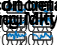

% 4.a.
% Beta exposures first 
figure(2);
subplot(3,2,1); plot(dateFactor(start_date+35:end),b(36:end,2)); recessionplot; title('RealRates Beta'); grid on; 
subplot(3,2,2); plot(dateFactor(start_date+35:end),b(36:end,3)); recessionplot; title('Inflation Beta'); grid on; 
subplot(3,2,3); plot(dateFactor(start_date+35:end),b(36:end,4)); recessionplot; title('Credit beta'); grid on; 
subplot(3,2,4); plot(dateFactor(start_date+35:end),b(36:end,5)); recessionplot; title('Economic beta'); grid on; 
subplot(3,2,5); plot(dateFactor(start_date+35:end),b(36:end,6)); recessionplot; title('Emerging Mkt beta'); grid on; 
subplot(3,2,6); plot(dateFactor(start_date+35:end),b(36:end,7)); recessionplot; title('Liquidity beta'); grid on;

## Monthly Return Attribution

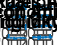

% 4.b.
figure(3);
subplot(4,2,1); plot(dateFactor(start_date+35:end),A(36:end,1)); recessionplot; title('Idiosyn Return Attr'); grid on; 
subplot(4,2,2); plot(dateFactor(start_date+35:end),A(36:end,2)); recessionplot; title('Alpha Attr'); grid on; 
subplot(4,2,3); plot(dateFactor(start_date+35:end),A(36:end,3)); recessionplot; title('RealRates Attr'); grid on; 
subplot(4,2,4); plot(dateFactor(start_date+35:end),A(36:end,4)); recessionplot; title('Inflation  Attr'); grid on; 
subplot(4,2,5); plot(dateFactor(start_date+35:end),A(36:end,5)); recessionplot; title('Credit Attr'); grid on; 
subplot(4,2,6); plot(dateFactor(start_date+35:end),A(36:end,6)); recessionplot; title('Economic Attr'); grid on; 
subplot(4,2,7); plot(dateFactor(start_date+35:end),A(36:end,7)); recessionplot; title('Emerging Mkt Attr'); grid on; 
subplot(4,2,8); plot(dateFactor(start_date+35:end),A(36:end,8)); recessionplot; title('Liquidity Attr'); grid on;